# Analyse de Donées - TD3

A first look on Séparateur a Vaste Marge (SVM) 

12/12/2022

clc; close all; clear all;

## 1 - Génération des données liéairement séparables

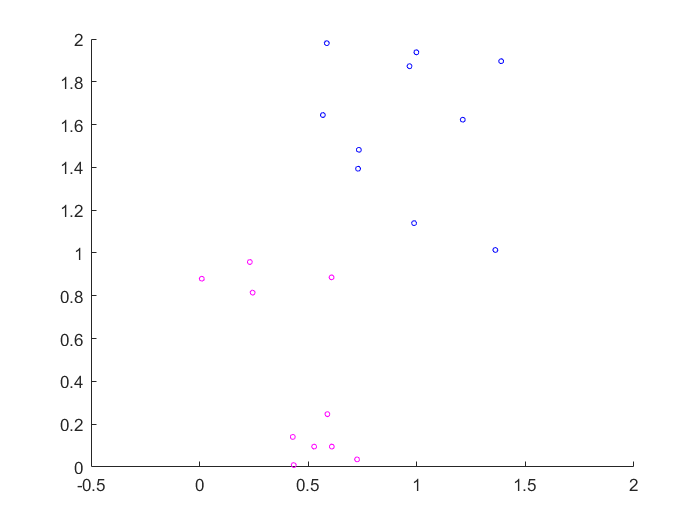

a = 0.5;
b = 1.5;
X2_a = [a + (b-a).*rand(10,1)];

a = 1;
b = 2;
X2_b = [a + (b-a).*rand(10,1)];

X2 = [X2_a , X2_b];
a = 0;
b = 1;
X1 = [a + (b-a).*rand(10,2)];

X = [X1; X2];
figure
hold on
plot( X2(:,1), X2(:,2), 'bo', 'MarkerSize', 3) % blue
plot( X1(:,1), X1(:,2), 'mo', 'MarkerSize', 3) % pink
xlim([-0.5 2])
ylim([0 2])

l = [ones(1,10), -1*ones(1,10)];

## 2 - Elaboration du séparateur à vaste marge

N = 20;
p = 2;

H = [eye(p), zeros(1, p)' ; zeros(1,p+1)]

H =      1     0     0
     0     1     0
     0     0     0


f = zeros(1,p+1)'

f =      0
     0
     0


On save que : $f(x) = \frac{1}{2} \text{x}^T \cdot \text{H} \cdot \text{x}  + f^T x$

comme T= 2, nous savons que : 


$$f(x) = \frac{1}{2} \cdot \left[\matrix{ x_1 & x_2  & x_3} \right] \cdot \left[\matrix{ 1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 0} \right] 
\cdot \left[\matrix{ x_1 \cr x_2 \cr x_3} \right]
 + \left[\matrix{ 0 \cr 0 \cr 0} \right] \cdot \left[\matrix{ x_1 & x_2 & x_3} \right]$$



$$\Rightarrow f(x) = \frac{1}{2} \left( x_1^2 + x_2^2\right)$$
 

Et aussi :


$$\left[\matrix{ -0.2311 & -0.9580 & -1.0000 \cr
-0.5274 & -0.0954 & -1.0000 \cr
...
} \right] \cdot 

\left[\matrix{ x_1 \cr
x_2 \cr
...
} \right] \leq 

\left[\matrix{ -1 \cr -1 \cr 
...
} \right]$$


Alors on va minimizer f(x) sous les contraites ci-dessus.

A = -[diag(l)*X, l']

A =    -0.2311   -0.9580   -1.0000
   -0.5274   -0.0954   -1.0000
   -0.7250   -0.0356   -1.0000
   -0.6074   -0.8862   -1.0000
   -0.5884   -0.2469   -1.0000
   -0.4334   -0.0089   -1.0000
   -0.2442   -0.8149   -1.0000
   -0.4290   -0.1405   -1.0000
   -0.0102   -0.8799   -1.0000
   -0.6088   -0.0954   -1.0000


e = -ones(1,N)'

e =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


z = quadprog(H,f,A,e)


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =    -3.1387
   -3.1850
    5.7291


w = z(1:2)

w =    -3.1387
   -3.1850


b = z(3)

b = 5.7291